clear all;
rosshutdown; % shut down existing connection to ROS

Shutting down global node /matlab_global_node_50860 with NodeURI http://192.168.212.1:40467/ and MasterURI http://192.168.212.129:11311.


ros_ip = "192.168.212.129";
rosinit(ros_ip,11311);

Initializing global node /matlab_global_node_17368 with NodeURI http://192.168.212.1:46559/ and MasterURI http://192.168.212.129:11311.


init

## program

% get_fixed
fixed_places
net = build_network;

  YOLOv2Net with properties:

         Name: 'robocup'
       Anchor: []
    DataStore: [1×1 matlab.io.datastore.CombinedDatastore]
     Detector: []
       LGraph: []



get_shape_change

File: get_shape_change.m Line: 1 Column: 1
Invalid use of operator.

return
% get_table %TO IMPROVE, some table parts still missing
% pcshow(pcMergedTop)
staring_time = rostime("now").Sec;
maxtime=600; %maximum number of seconds for executethe rest of the program
best_points={2,3,4,5,6,7}; %to populate with best points to classify and grasp
num_best=size(best_points,2); %number of points
i=0; %initializing idx
while(maxtime>(rostime("now").Sec-staring_time)) %we cycle for maxtime seconds
    if cellfun('isempty',best_points) 
        break %stop if no more points to check
    end
    i=i+1;
    i=max([mod(i,num_best+1),1])
    current_point=best_points{i};
    if isempty(current_point)
        continue
    end
    goto_point(current_point); % NEED IMPLEMENTATION in trajectory_stuff
    rgb=get_image('r');
    di=get_image('d');
    [prediction, bboxes, scores, labels] = classify(net,rgb);
    if isempty(bboxes)
        best_points{i}=[]
        continue %nothing to looking for, we remove the point here
    end
    
    points = p3D_from_bboxes(bboxes,di,'base_link') %project bounding box centers on the image to the world
    if isstring(points)
        continue %if we fail to take the transformation we skip this point for now and go to the next
    end
    pc_photo = get_pcloud_from_photo
    %% at this point a function that takes all the points or just the first and grasp the associated bottle/can(s)
    %% it's also possible to check the nearest bottle given the points (this solutio need another cell with all the 
    %% bot/cans locations) and remove from best point if we grasp it correctly (we also perform de-noising here)
    point=points(:,1)
    pcloud_box=get_pointcloud(pc_photo,point)  % NEED IMPLEMENTATION in grasping/models
    item_dir = get_direction(pcloud_box) % NEED IMPLEMENTATION in grasping
    correctly_removed= grasp_and_throw(item_dir,current_point); % NEED IMPLEMENTATION in grasping
    %%we go back and update the table
    goto_point(current_point) % NEED IMPLEMENTATION in trajectory_stuff
    update_table % NEED IMPLEMENTATION in image_handling/models, we update the table from current point
%     if correctly_removed %parameters from grasp, correctly removed false if eg unreachable of not a real item 
%         best_points{i}=[]
%         %% remove also from items cell if that solution is adopted
%     end
end

## test

net = build_network;

  YOLOv2Net with properties:

         Name: 'robocup'
       Anchor: []
    DataStore: [1×1 matlab.io.datastore.CombinedDatastore]
     Detector: []
       LGraph: []



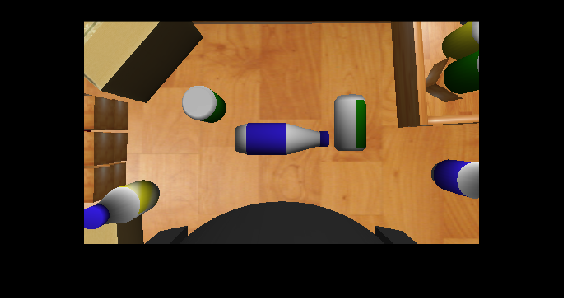

rgb=get_image('r');
di=get_image('d');
[prediction, bboxes, scores, labels] = classify(net,rgb);
imshow(rgb)

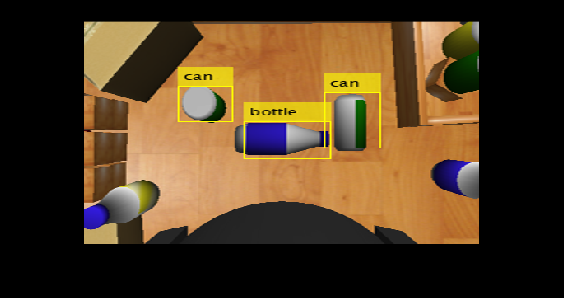

imshow(prediction)

scores

scores = 3×1 single column vector
    0.5280
    0.6584
    0.7317


## test2

pc = get_pcloud_from_photo;

xyz = 129600×3 single matrix
   -0.4029   -0.2263    0.5831
   -0.4012   -0.2263    0.5831
   -0.3995   -0.2263    0.5831
   -0.3978   -0.2263    0.5831
   -0.3962   -0.2263    0.5831
   -0.3945   -0.2263    0.5831
   -0.3928   -0.2263    0.5831
   -0.3911   -0.2263    0.5831
   -0.3894   -0.2263    0.5831
   -0.3878   -0.2263    0.5831


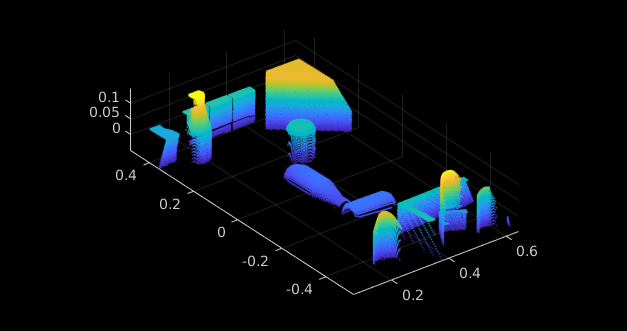

pcshow(pc)

points = p3D_from_bboxes(bboxes,di,'base_link') %project bounding box centers on the image to the world

points =     0.4296    0.3964    0.3477
    0.1697   -0.1779   -0.0174
    0.0557   -0.0054   -0.0055


points = p3D_from_bboxes(bboxes,di,'base_link') %project bounding box centers on the image to the world

points =     0.4296    0.3964    0.3477
    0.1697   -0.1779   -0.0174
    0.0557   -0.0054   -0.0055


pc_filtered = get_pointcloud(pc,points(:,1)')

pc_filtered =   pointCloud with properties:

     Location: [1014×3 double]
        Count: 1014
      XLimits: [0.3924 0.4578]
      YLimits: [0.1367 0.2048]
      ZLimits: [0.0356 0.0506]
        Color: []
       Normal: []
    Intensity: []


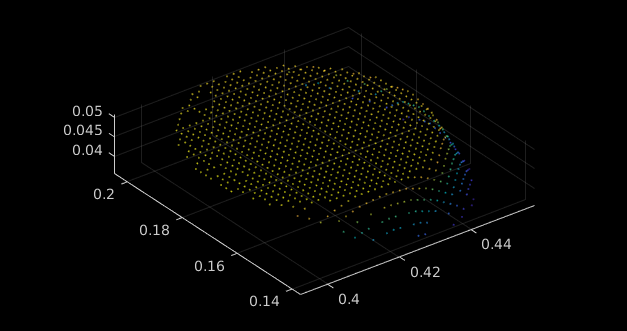

pcshow(pc_filtered)

pcomp = get_direction(pc_filtered)

pcomp =     0.2778
    0.9606
    0.0117


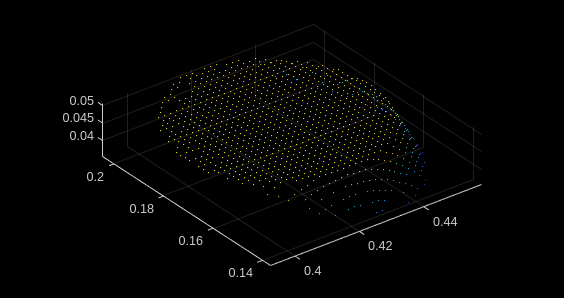

[model,inlierIndices] = pcfitcylinder(pc_filtered,0.05,pcomp);
pfinal = select(pc_filtered,inlierIndices);
pcshow(pfinal)

pcomp = get_direction(pfinal)

pcomp =     0.2778
    0.9606
    0.0117
